# Symbolic Math in MATLAB

## Defining symbolic variables

### Symbolic Variables

To define a symbolic variable, we use the *syms *command. Let's create a symbolic function for the height a vertically launched rocket will be at over time (ignore air resistance):


$$y = -4.9 t^2 + v_0t + y_0$$


We will first declare our three variables; time, $t$, intial velcoity, $v_0$, and initial height $y_0$.

syms t v_0 y_0

### Symbolic Function

Now that we have our symbolic variables declared, we can now create our symbolic function of height:

f(t,v_0,y_0) = -4.9*t^2 + v_0*t + y_0

$$f(t, v\_0, y\_0) = -\frac{49\,t^{2}}{10}+v_{0}\,t+y_{0}$$

Alternatively, a function can be decalred in the following manner. 

f1 = @(t,v_0,y_0) -4.9*t^2 + v_0*t + y_0

f1 = function_handle with value:
    @(t,v_0,y_0)-4.9*t^2+v_0*t+y_0


In this manner, using syms to first declare the variables would not be necessary. 

### Evalualting a Function

Suppose we want to evaluate our function at half second increments from 0 to 10 seconds given a inital velcoity and height. We can do this in the following manner:

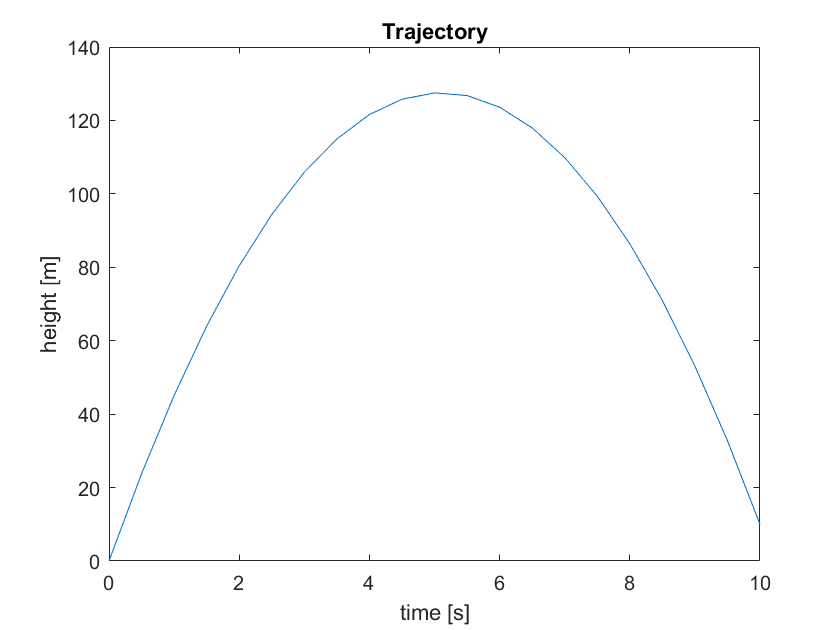

t = 0:0.5:10;
v_0 = 50;
y_0 = 0;

y = f(t,v_0,y_0);

plot(t,y)
title('Trajectory')
xlabel('time [s]')
ylabel('height [m]')

## Combining Functions

Two functions can be added together by simply adding, subtracting, multiplying or dividng them. For example,

syms t

y1 = cos(t);
y2 = sin(t);

y = y1*y2

$$y = \cos\left(t\right)\,\sin\left(t\right)$$

## Differentiating Functions

To differentiate functions, you can use the *diff *function. For example using *y *defined previously. 

dy(t) = diff(y)

$$dy(t) = {\cos\left(t\right)}^{2}-{\sin\left(t\right)}^{2}$$

## Integrating Functions

To integrate a function, you can use the *int* function. This will calculate the indefinite integral for the function. You must specify which variable(s) you are integrating with respect to when using this function. 

Y(t) = int(y,t)

$$Y(t) = \frac{{\sin\left(t\right)}^{2}}{2}$$

$$ans = \frac{1}{2}$$

## Convert String to Function

To convert a given string to a function, you can use the *str2func *function. You must concatentate the *@(var) *to you function string. This is so MATLAB knows what the variables are in your function. Then you can convert the combination to a function.

name = 'x^2*y+x*y+x*y^2';
func = str2func(strcat('@(x,y)',name))

func = function_handle with value:
    @(x,y)x^2*y+x*y+x*y^2


## References

This information is based on that found on the MATLAB Documentaion available online. The main link directing you to this documentation can be found below:[https://www.mathworks.com/help/symbolic/symbolic-variables-expressions-and-functions.html](https://www.mathworks.com/help/symbolic/symbolic-variables-expressions-and-functions.html)